# Kapitel 2: Retlinet bevægelse / Kinematics of Particles

## *Opgave 2/1:*

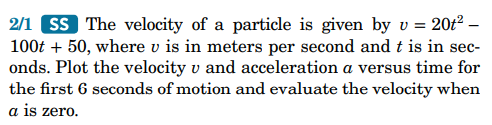


$$v = 20*t^2-100*t+50$$
 


$$a = \frac{dv}{dt}=\dot{v} \rightarrow a = 40*t-100$$
 

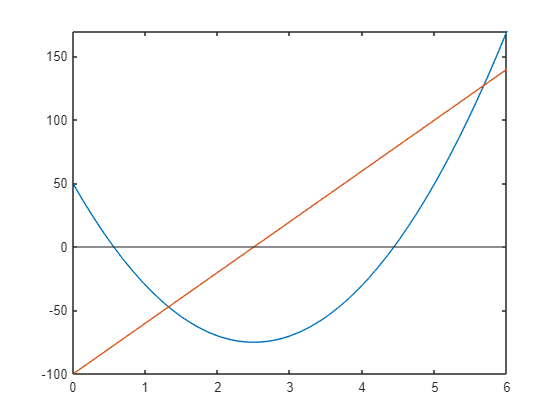

v = @(t) 20*t.^2-100.*t+50;
a = diff(v,t); % = %a = @(t) 40.*t-100;

fplot(v,[0 6]) 
hold on
xline(0)
yline(0)
fplot(a,[0 6]) 
hold off

## ***Opgave 2/9:***

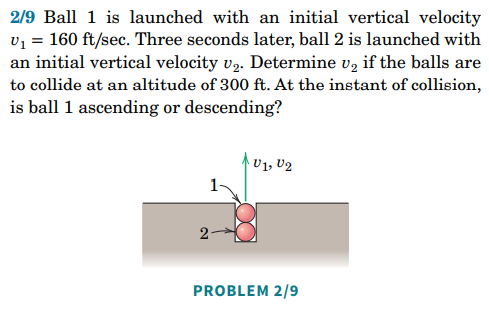

Da vi godt kan lide SI enheder, så konverter vi ft til m:

- 160 ft/sec = 48,77 m/s

- 300 ft = 91,44 m

Vi kan bestemme tiden det tager for bold 1 at flyve de 300 meter via sted formlen.

Når vi har tiden, så kan vi finde hastigheden for bold 2.

clear all
syms t v2;

% De kendte værdier:
v0 = 48.77;
g = -9.82;

% Strækningsformlen for bold 1:
s_b1 = v0*t+(1/2)*g*t^2;

% Udregning af tiden til 91.44 meter på vej ned:
s = v0*t+(1/2)*g*t^2-91.44;
eq = vpa(solve(s,t),3);
t_b10 = 7.42;

% Da vi har tiden til 91.44 meter, så kan vi bestemme hastigheden som bold
% 2 skal have ved at begrænse tiden med 3 sek og solve for v2.

% Hastigheden via strækningen:
v_b2 = v2*(t_b10-3)+(1/2)*g*(t_b10-3)^2-91.44;
eq2 = vpa(solve(v_b2,v2),3)

$$eq2 = 42.4$$

## ***Opgave 2/17***

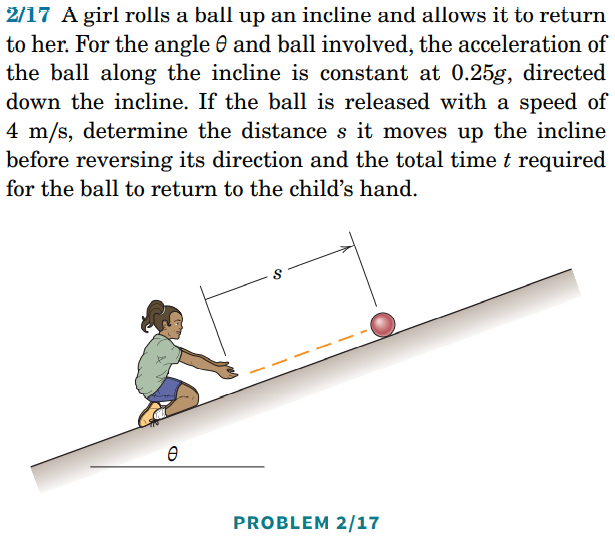

Informationer:

- Accelerationen er: a = 0.25 * g

- Hastigheden er: v0 = 4 

Der skal bestemmes:

- Strækningen bolden bevæger sig op af bakken, s.

- Bestem tiden til nul.

Til denne opgave skal vi anvende strækningsformlen:

- 
$$s = s_{0} + v_{0}*t+\frac{1}{2}*a*t^2$$
 

clear all

syms t;

a = 0.25 * (-9.81)

a = -2.4525

v0 = 4

v0 = 4

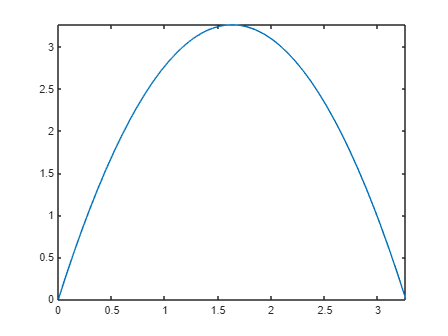


% Vi opsætter strækningsfunktionen, hvorefter vi plotter den:
s_bold = v0*t + (1/2)*a*t^2;
fplot(s_bold,[0 3.26]);

% Vi opsætter en der udregner tiden til nul:
tid_bold0 = vpa(simplify(solve(s_bold,t)),3);
% Vi må antage, at den længste strækning som bolden når, før den kører tilbage, er ved tid-halve:
tidHalve = 3.26/2;
s = v0*tidHalve + (1/2)*a*tidHalve^2

s = 3.2620

## ***Opgave 2/39***

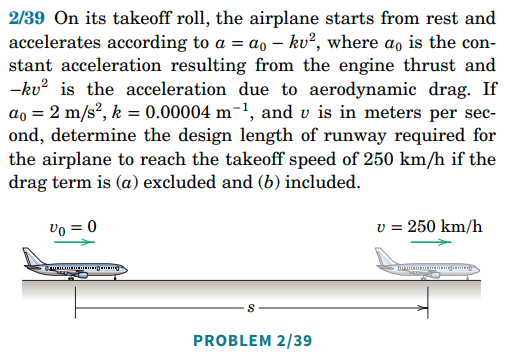

Informationer:

- Accelerationen: $a = a_0 - k*v^2$

- Luftmodstanden: $k = 0.00004$

- Den konstante acceleration: $a_0 = 2 \frac{m}{s}$

- Take off hastigheden er: $v_{takeoff} = 250 km/h \rightarrow \frac{250*1000}{3600} = 69.44 \frac{m}{s}$

Det der skal bestemmes:

- Længden som kørebanen skal have, hvis luftmodstanden er regnet med og uden.

Det som vi skal vide for at løse opgaven:

- Tiden det tager at nå de 69.44 m/s.

clear all
syms t;

a0 = 2;
k = 0.00004;
v_takeoff = 69.44444;

% Vi starter med at finde tiden til hastigheden takeoff uden bidrag fra luftmodstanden:
TidTakeoff = a0*t - v_takeoff;
eq = vpa(solve(TidTakeoff,t),3);
t_takeoff = 34.7;

% Nu kan vi finde strækningen, som vores fly bevæger sig, før det når vores
% hastighed:
s_udenModstand = ((1/2)*a0*t_takeoff^2); % 1204.1 meter
s_udenModstand2 = v_takeoff^2/(2*a0); % 1205.6 meter

% Nu kan vi medtage vores luftmodstand:
% Igen starter vi med at bestemme tiden til 250 km/h er nået:
% Vi kan finde tiden ved at isolere for den i hastighedsformlen. 
% Når vi kender den ønskede hastighed, så kan vi flytte svaret over på
% højresiden, hvor vi så kan solve for tiden til at acceleratioen med den
% fratrukkede hastighed giver nul.
% Dette resultat fortæller, hvor langtid det tager vores acceleration at nå
% vores ønskede hastighed.
TidModstand = a0*t - k*(v_takeoff^2)*t - v_takeoff;
eq2 = vpa(solve(TidModstand,t),8); 
TidTakeoffModstand = 38.42869;

% Indsætter vi tiden i strækning/flytningsformlen, så kan vi finde den
% ønskede længde:
s = vpa(0.5*v_takeoff*TidTakeoffModstand, 8)

$$s = 1334.3294$$

# Kapitel 2: Retlinet bevægelse / Kinematics of Particles

## ***Opgave 2.47***

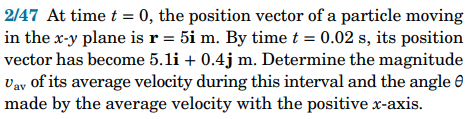

% At t = 0, x(t) = 5 & y(t) = 0
% At t2 = 0.02, x(t2) = 5.1 & y(t2) = 0.4

% First we set up the unknown i and j
syms i j

% From here the vector are presented from t to t2.
r_0 = 5*i;
r_t2 = 5.1*i + 0.4*j;

t2 = 0.02;

% We start by displaying the v_av vektor and then remove the i & j
% components to display the actual v_av for t2.
vektor_v_av = ((r_t2-r_0)/t2)

$$vektor\_v\_av = 5\,i+20\,j$$

v_av = sqrt(5^2 + 20^2)

v_av = 20.6155

% Now we find the angle made by the velocity with the positive x-axis.
theta = rad2deg(atan(20/5))

theta = 75.9638

## ***Opgave 2.48***

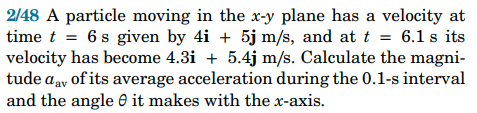

syms i j
v_t = 4*i + 5*j;
v_t1 = 4.3*i + 5.4*j;

delta_t = 6.1 - 6;

vektor_a_av = (v_t1-v_t)/delta_t

$$vektor\_a\_av = 3\,i+4\,j$$

a_av = sqrt(3^2 + 4^2)

a_av = 5

theta = rad2deg(atan(4/3))

theta = 53.1301

## ***Opgave 2.49***

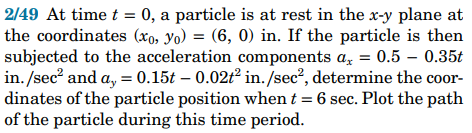

syms t

% We start by placing our START coordinates & verlocity of our object.
% We see that the objekt is at rest:
x_0 = 60; 
y_0 = 0;

% Rest == zero movement.
v_x0 = 0;
v_y0 = 0;

% We are asked to determine the coordinates of the object at t = 6 s. After
% wards plot the path.

% First we need to know the velocity for our x & y components:
% For x:
a_x = 5-3.5*t;
v_x = vpa(v_x0 + int(a_x,t),6);
x = vpa(x_0 + int(v_x,t),6)

$$x = 60.0-1.0\,t^{2}\,\left(0.583333\,t-2.5\right)$$

x_6 = 60 - 1*(6^2)*(0.583333*6-2.5)

x_6 = 24.0001

% For y
a_y = 1.5*t-0.2*t^2;
v_y = vpa(v_y0 + int(a_y,t),6);
y = vpa(y_0 + int(v_y,t),6)

$$y = -1.0\,t^{3}\,\left(0.0166667\,t-0.25\right)$$

y_6 = -1*(6^3)*(0.016667*6-0.25)

y_6 = 32.3996

## ***Opgave 2.50***

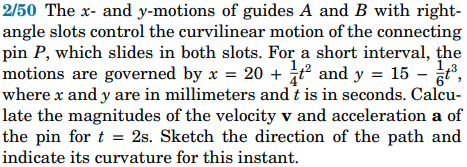

clear all;
syms t
% It's need for us to calculate the velocity and acceleration of an object
% for time = 2 sec.

% The x- & y-coordinates movement:
x = 20 + 0.25*t^2;
y = 15-(1/6)*t^3;

% The velocities:
v_x = diff(x,t);
v_y = diff(y,t);
% The acceleration:
a_x = diff(v_x,t);
a_y = diff(v_y,t);

%Combined:
v = vpa(sqrt(v_x^2 + v_y^2),6);
v_2 = sqrt(0.25*2^4 + 0.25*2^2);

a = vpa(sqrt(a_x^2 + a_y^2),6);
a_2 = sqrt(2^2+0.25);

## ***Opgave 2.51***

clear all;
syms t h
% We start by listing the information:
alpha = 30;
v = 1000/3.6; %m/s
g = 9.38;     %m/s^2

% We find the scalar expression for the y-component and afterwards solve
% for t == 0.
v_y = vpa(v * cos(deg2rad(alpha)) - g * t,6);
ab = solve(v_y,t)

$$ab = 25.646333919226002503163016496829$$


% Now we can find the maximum altitude h:
v_y2 = vpa(v_y^2+2*(-g)*h,6)

$$v\_y2 = {\left(9.38\,t-240.563\right)}^{2}-18.76\,h$$

h = (v * cos(deg2rad(alpha)))^2/(2*g)

h = 3.0848e+03

## ***Opgave 2.53***

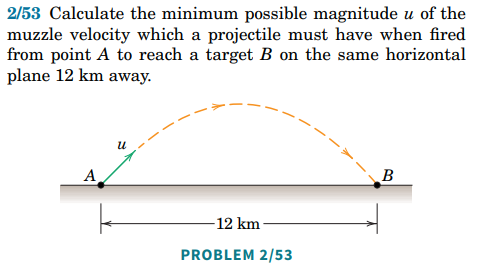

Formlen der skal anvendes til denne type problem er:


$$s = \frac{V^2 - V_0^2}{2*a}$$


% The magnitude in this assignment is to be understood as velocity.
clear all;
syms t;

alpha = 45;
g = 9.81;
s = 12000;
v = sqrt(1*g*s)

v = 343.1035

## ***Opgave 2.54***

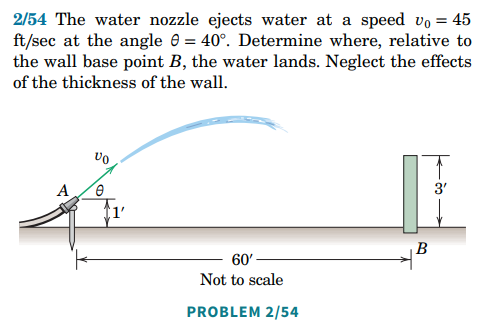

% We start by listing the information given by the assignment:
clear all;
syms t
y_0 = 0.3; %meter
alpha = deg2rad(40);
v_0 = 14; % m/s
g = 9.81; % m/s^2

% We start by finding out how far the water get and the time till it
% reaches it.
v_x = vpa(v_0 * cos(alpha),6);
v_y = vpa(v_0 * sin(alpha),6)

$$v\_y = 8.99903$$

% We set up the expressions for distance and isolate for time:
y = y_0 + v_y * t - 0.5*g * t^2

$$y = -\frac{981\,t^{2}}{200}+8.9990265356116196926450356841087\,t+\frac{3}{10}$$

vpa(solve(y,t),6)

$$ans = \left(\begin{array}{c} -0.0327522\\ 1.86742 \end{array}\right)$$

x = v_x * 1.86742

$$x = 20.027373995569221460755215957761$$

% It is now determined that the water goes further than the wall.
% So now we will see if the water hits the wall or goes above.
% We do this by isolating for the v_x by the distance to the wall:
TimeB = 19/v_x

$$TimeB = 1.7716241783795356490157531226089$$

y_B = y_0 + v_y * TimeB - 0.5*g * TimeB^2

$$y\_B = 0.84780380706855275023511477667938$$

% Since the wll is 0.914 meters high the water hits the wall and does not
% get further then the wall.

## *Opgave 2.55*

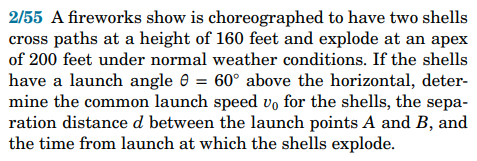

clear all;
syms t v_0
% We are asked to find:
% v_0
% the distance between the two platforms
% The at explosion= y = 200.

% We start by listing know information:
g = 9.81;
alpha = 60;
y = 60;

% We can find v_0 from the distance formula:
v_0 = vpa(solve(0 == (v_0 * sin(deg2rad(60)))^2 - 2*g*y),6);
v_y = 39.6182 * sin(deg2rad(alpha))

v_y = 34.3104

% Now we want the time for the rocket to reach 48 meters:
vpa(solve(48 == v_y * t - 0.5*g*t^2,t),6)

$$ans = \left(\begin{array}{c} 1.93336\\ 5.06162 \end{array}\right)$$

x = 39.6182*cos(deg2rad(alpha)) * 1.93336

x = 38.2981

d = 2*x

d = 76.5962

## *Opgave 2.63*

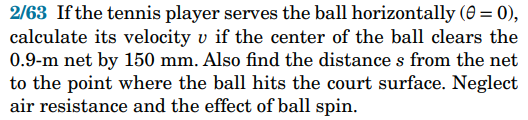

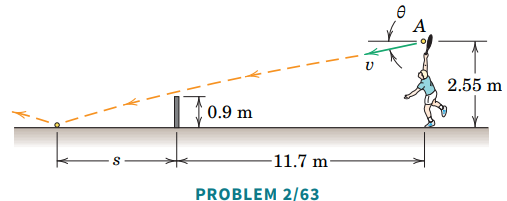

We start by finding an expression for y and solve for time.

Then we use the found time to find v_0 by isolating it in the x-distance formula.

clear all
syms y y_0 v_y0 g t theta v_y v_0 x

y = y_0 + v_y *t - 0.5*g*t^2

$$y = -\frac{g\,t^{2}}{2}+v_{y}\,t+y_{0}$$

% Finding the time the ball reaches y of 1.05 m.
y_0 = 2.55;
y = 1.05;
g = 9.81;
theta = deg2rad(0);
v_y = v_y0 * sin(theta);
t_net = vpa(solve(y == y_0 + v_y *t - 0.5*g*t^2,t),3);
% time = 0.553
% Now we isolate for velocity in the x-distance formula:
v = vpa(solve(11.7 == v_0*cos(theta)*0.553,v_0),3)

$$v = 21.2$$

vpa(solve(0 == y_0 + v_y *t - 0.5*g*t^2,t),3)

$$ans = \left(\begin{array}{c} -0.721\\ 0.721 \end{array}\right)$$

% Since we now got the time for it to reach zero, we can insert the time in
% the x-distance formula and calculate the distance s:
s = vpa(solve(x == 21.2 * 0.721,x),3)

$$s = 15.3$$

## *Opgave 2.64*

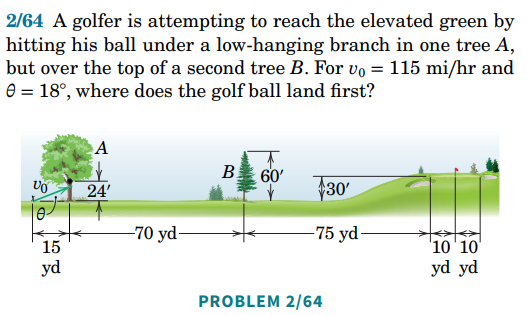

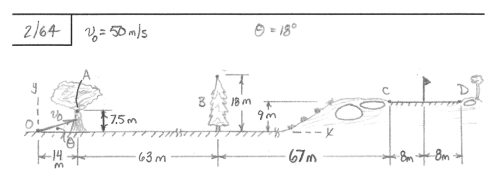

% We start by finding the time for y = 0. From here we can input the time
% as function and put it a graph, where we can add the x-axis in
% corrolation to the y distance.
clear all
syms t g y x v_0 theta 

% We start by finding out if he even parses the branch:
theta = deg2rad(18);
v_0 = 50;
x_1 = 14;
x_2 = x_1 + 63;
g = 9.81;
TimeToBranch = vpa(solve(x_1 == v_0 * cos(theta) * t,t),3); %0.294
% Now we can check if we even pass the branch:
Branch_check = vpa(solve(y == v_0*sin(theta)*0.294-0.5*g*0.294^2,y),3); % Check passed

% Now we check if we can get pass the tree:
% First we isolate the time in the x-distance formular, and then we
% corrolate with the y-height for the time:
TimeToTree = vpa(solve(x_2 == v_0 * cos(theta) * t,t),3); %1.62
% Now we can check if we even pass the branch:
Branch_check = vpa(solve(y == v_0*sin(theta)*1.62-0.5*g*1.62^2,y),3) % Check failed

$$Branch\_check = 12.2$$

## *Opgave 2.66*

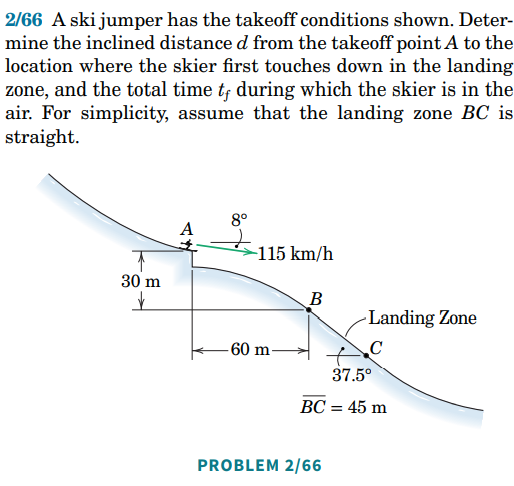

We start by finding the x- and y-length to the landing zone.

From there we isolate the time to the landing zone.

% we start off by doing somme sinus-relations:
clear all
syms t
a = 60;
b = 30;
e = sqrt(a^2 + b^2);
bc = 45;
d = e + bc

d = 112.0820

Bc = rad2deg(180 - 90 - 37.5);
BC = (sin(deg2rad(Bc))) * bc;
yC = a + BC;
xC = sqrt(bc^2 - BC^2) + a;
% Now we can find the time from the distance in the x-axis:
v_0 = 115/3.6;
theta = deg2rad(8);
x_time = vpa(solve(xC == v_0*cos(theta)*t,t),5) 

$$x\_time = 2.7731$$

% I stopped this assignment since it was weird.

## *Opgave 2.69*

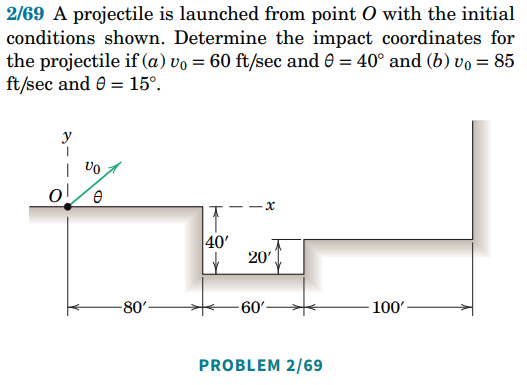

We complete this assignment in the same manner as the golfer assignment:

clear all
syms t y x
g = 9.81;
% case a:
v_0 = 18;
theta = deg2rad(40);
% 0-24 meter time:
x_time1 = vpa(solve(24 == v_0*cos(theta) * t,t),4);
y_1 = vpa(solve(y == v_0*sin(theta)*x_time1 - 0.5*g*x_time1^2,y),4);
% 24-42 meter time:
x_time2 = vpa(solve(42 == v_0*cos(theta) * t,t),4);
y_2 = vpa(solve(y == v_0*sin(theta)*x_time2 - 0.5*g*x_time2^2,y),4);

% case b:
v_0 = 25;
theta = deg2rad(15);
% 0-24 meter time:
x_time1 = vpa(solve(24 == v_0*cos(theta) * t,t),4);
y_1 = vpa(solve(y == v_0*sin(theta)*x_time1 - 0.5*g*x_time1^2,y),4);
% 24-42 meter time:
x_time2 = vpa(solve(42 == v_0*cos(theta) * t,t),4);
y_2 = vpa(solve(y == v_0*sin(theta)*x_time2 - 0.5*g*x_time2^2,y),4);
% 42-72 meter timer:
x_time3 = vpa(solve(72 == v_0*cos(theta) * t,t),4);
y_3 = vpa(solve(y == v_0*sin(theta)*x_time3 - 0.5*g*x_time3^2,y),4);
% Since this is not the right time, we solve for -6 meters:
y_3 = vpa(solve(-6 == v_0*sin(theta)*t - 0.5*g*t^2,t),4); % time = 1.947
x_caseb = vpa(solve(x == v_0*cos(theta) * 1.947),4)

$$x\_caseb = 47.02$$

## *Opgave 2.71*

clear all
syms t v_0
theta = deg2rad(30);
g = 9.81;
t_net = 3.5/(v_0*cos(theta));
v = vpa(solve(0.2 == 0.3 + v_0 * sin(theta) * t_net - 0.5 * g *t_net^2,v_0),5) % 6.1536

$$v = \left(\begin{array}{c} -6.1463\\ 6.1463 \end{array}\right)$$

t_net = 4.1/(v_0*cos(theta));
v = vpa(solve(0.2 == 0.3 + v_0 * sin(theta) * t_net - 0.5 * g *t_net^2,v_0),5) % 6.1536

$$v = \left(\begin{array}{c} -6.6754\\ 6.6754 \end{array}\right)$$

# Kapitel 2: Plan kurvebevægelser, Normal og tangent (n-t)

## *Opgave 2.81*

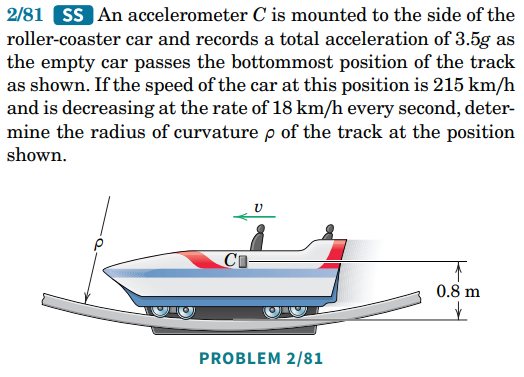

Given the information provided in the assignment; the following can be stated:

- 
$$a = 3 * 9.81$$


- 
$$v = 215 / 3.6 = 59.722$$


- 
$$a_t = 5$$


Fra bogen er det oplyst at radius er angivet som: 

- 
$$a_n = v^2/\rho$$


% we start by finding the normal acceleration:
a = 3.5*9.81;
a_t = 5;
a_n = sqrt(a^2 - a_t^2);

% Now that a_n is found we can solve for the radius of the lane:
v = 59.722;
rho = v^2/a_n;

% Now we add the 0.8 meters the center is located:
rho + 0.8

ans = 105.7992

## *Opgave 2.87*

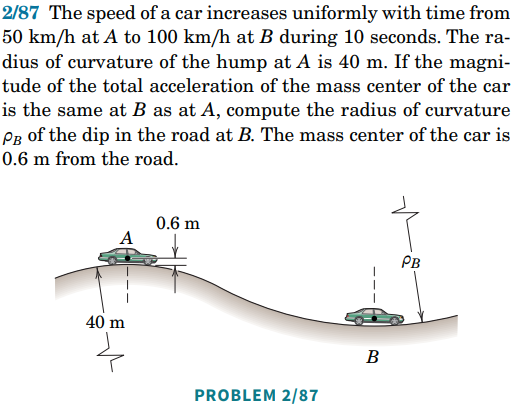

clear all
% We start by listing our calculation our speeds:
SpeedA = 50/3.6;
SpeedB = 100/3.6;

time = 10;

a_t = (SpeedB-SpeedA)/time;
%Since the total acceleration at point A & B equals on another we can
%calculate the acceleration at point A:
rhoACar = 40 + 0.6;
a_n = SpeedA^2/rhoACar;
a = sqrt(a_t^2 + a_n^2);

% Now that we got both total accelerations we can find the radius at B:
rhoB = SpeedB^2/a_n

rhoB = 162.4000

rho = rhoB+0.6

rho = 163

## *Opgave 2.88*

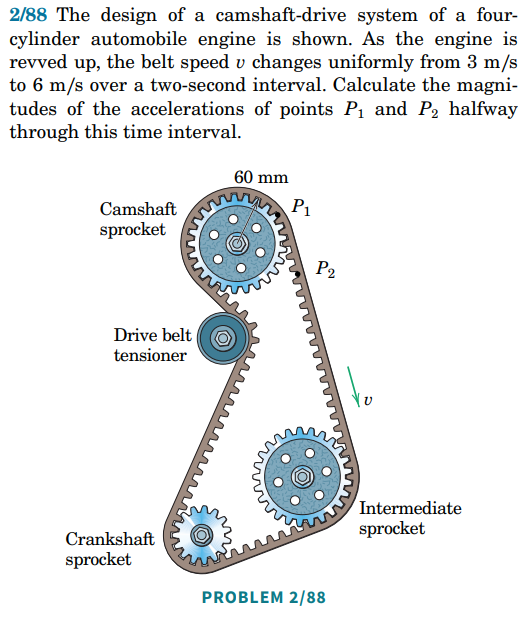

% We start by defining a_t:
Speed1 = 3;
Speed2 = 6;
t = 2;
a_t = (Speed2-Speed1)/t; %a_p2

% Halfway through the time interval the speed is:
v = Speed1 + a_t;

% We can now find a_n halfway through:
rho = 0.06;
a_n = v^2/rho; %a_p1

## *Opgave 2.95*

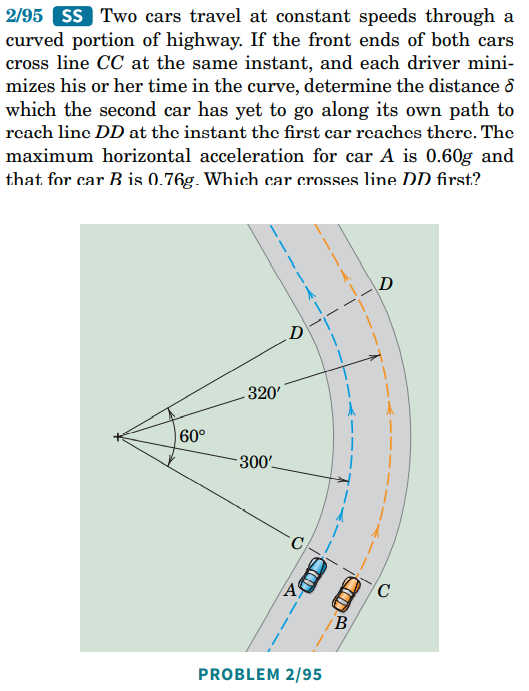

clear all
% We are to figure out which car passes DD first:
g = 9.81;
ARho = 90;
BRho = 96;
aA = 0.6 *g;
aB = 0.76 *g;

% The given acceleration found is the normal acceleration.
% So from here we solve for the speed:
v_A = sqrt(aA * ARho);
v_B = sqrt(aB * BRho);
% If we calculate the circle arc length for both lanes, then we
% can divide the length with the individual speeds to find the time:
LengthA = ARho * 60 * pi/180;
LengthB = BRho * 60 * pi/180;

% Now we solve for time:
timeA = LengthA/v_A

timeA = 4.0949

timeB = LengthB/v_B

timeB = 3.7577

% Since B's time is "smaller" car B will win the race.

# Kapitel 2: Plan kurvebevægelse, Polære (r-Θ) koordinater. (2.6)

## *Opgave 2.114*

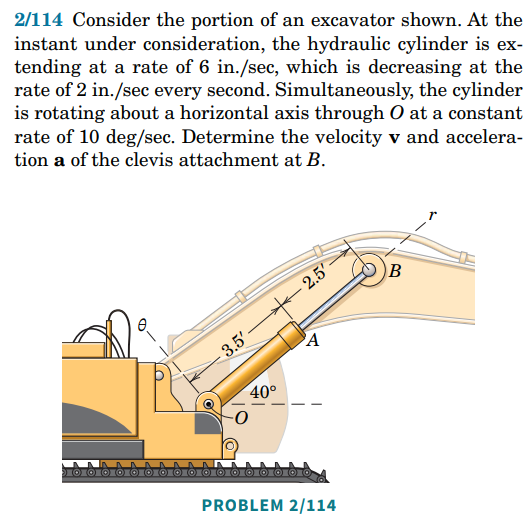

clear all
syms x
% We start by listing our components:
thetaDot = 10 * pi/180; %rads
thetaDotDot = diff(sym(thetaDot));
rDot = 0.15; %m/s
rDotDot = -0.05; %m/s^2
r = 1.75;

%  Now that our elements are listed we can calculate the accelerations:
a_r = rDotDot - r*thetaDot^2;
a_theta = vpa(r*thetaDotDot + 2*rDot*thetaDot,5)

$$a\_theta = 0.05236$$

## ***Opgave 2.118***

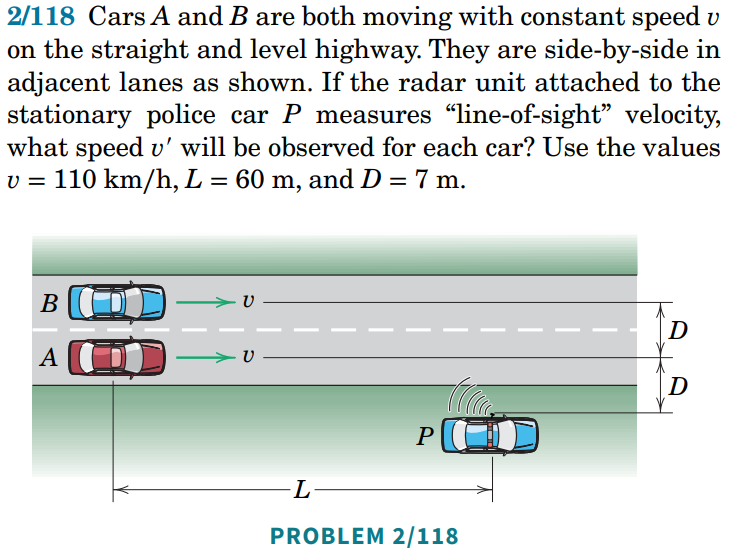

- Each car has a speed of: $110 \frac{km}{m}$

- Length from the police car of: $60 meters$

- A has a horizontal distance of 7 meters

- B has a horizontal distance of 14 meters

SpeedCars = 110;
v = 110/3.6;

%Distances:
D = 7;
L = 60;

% The angle of the police car to A:
Vinkel_A = rad2deg(tan(D/L))

Vinkel_A = 6.7150


% The angle of the police car to B:
Vinkel_B = rad2deg(atan(((2*D)/L)))

Vinkel_B = 13.1340

% The velocity of car A in relation to the cop car:
v_A = v * cos(deg2rad(Vinkel_A)) %* 3.6

v_A = 30.3459


% The velocity of car B in relation to the cop car:
v_B = v * cos(deg2rad(Vinkel_B)) %* 3.6

v_B = 29.7563

## ***Opgave 2.122***

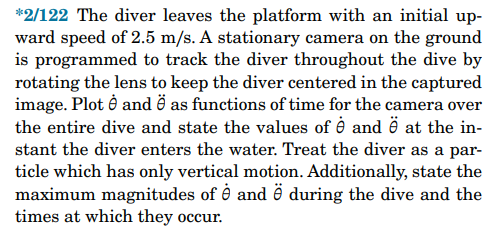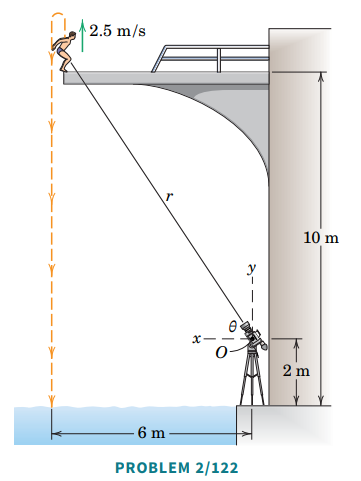

% We start by listing our knowns:
v_y = 2.5;
g = 9.81;
x = 6;
y_0 = 8;
y_f = -2;
Vinkel_WH = rad2deg(atan(y_0/x)); % starting angle; 53.1301°
% For the next bit we need a symbolic bit:
syms t;
y = @(t) y_0 + v_y .*t - 0.5 * g .* t.^2;
v = @(t) v_y - g.*t;
r = @(t) sqrt(x^2 + y(t).^2)

r = function_handle with value:
    @(t)sqrt(x^2+y(t).^2)


theta = @(t) atan(y(t)./x)

theta = function_handle with value:
    @(t)atan(y(t)./x)



% Time is takes the diver to reach the water:
time_f = vpa(solve(-2 == y(t),t),5); % 1.7052 secs.

% Now we setup the r-dot, r * theta-dot, a-r, a-theta
thetadot = @(t) (v(t) .* cos(theta(t)))./r(t)

thetadot = function_handle with value:
    @(t)(v(t).*cos(theta(t)))./r(t)


thetadotdot = @(t) (-g .* cos(theta(t)) - 2 .* ( v(t) .* sin(theta(t)) ) .* ((v(t) .* cos(theta(t))./r(t))))./r(t)

thetadotdot = function_handle with value:
    @(t)(-g.*cos(theta(t))-2.*(v(t).*sin(theta(t))).*((v(t).*cos(theta(t))./r(t))))./r(t)


% Now we plot the functions from zero to time final:

t_f = linspace(0,1.7052,101); 
plot(t_f,thetadotdot(t_f))

plot(t_f,thetadot(t_f))

# Kapitel 2: Relativ bevægelse, Translaterende koordinatsystem 2.8

## *Opgave 2.150*

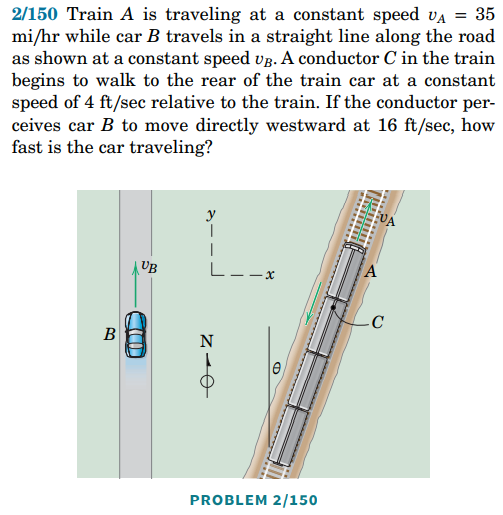

clear all
% We start by listing the known informations:
SpeedTrainA = 55/3.6; % 55 km/t -> m/s.
SpeedConductorC = -1.2; % 1.2 m/s.
SpeedBC = -4.8; % 4.8 m/s.

% To eace it a bit. We will find the real horizontal speed of the
% conductor:
syms j i theta;

v_C = (SpeedTrainA+SpeedConductorC)*(sin(theta)*i + cos(theta)*j);
v_B = (SpeedTrainA+SpeedConductorC)*(sin(theta)*i + cos(theta)*j) + SpeedBC*i;
v_B_i = (SpeedTrainA+SpeedConductorC)*sin(theta)+SpeedBC;
v_B_j = (SpeedTrainA+SpeedConductorC)*cos(theta);

% Now we can split the equation for x & y components and afterwards find
% the angle theta.

Solve_i = vpa(solve(v_B_i,theta),5)

$$Solve\_i = \left(\begin{array}{c} 0.34794\\ 2.7937 \end{array}\right)$$

% Now we examine the first Sin value:
theta = rad2deg(asin(0.34794))

theta = 20.3614

Solve_j = (SpeedTrainA+SpeedConductorC)*cos(deg2rad(theta)) % m/s.

Solve_j = 13.1982

## *Opgave 2.151*

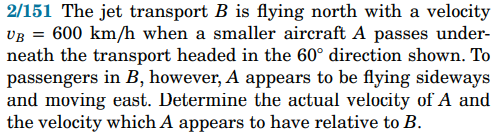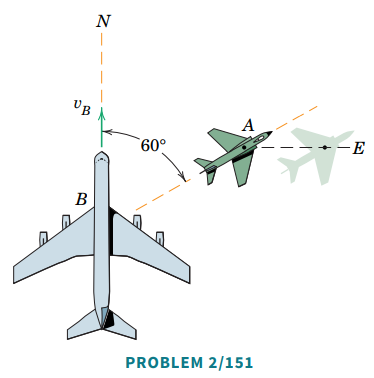

clear all
% It is mentioned in the assignment that the smaller plane A passes plane
% B. Plane B has a velocity of 600 km/h.
% Since we are moving; we can find v_A as:
v_B = 600;
theta_BA = deg2rad(60);
v_A = vpa(600/cos(theta_BA),3) %km/h

$$v\_A = 1200.0$$

v_BA = vpa(600*tan(theta_BA),3) %km/h

$$v\_BA = 1040.0$$

% v_A is diveded since we want to find that particles true speed.
% v_BA is multiplied as we would a normal speed equation.


## *Opgave 2.154*

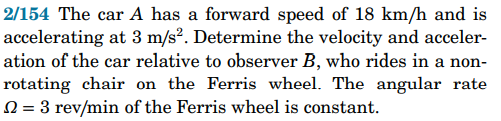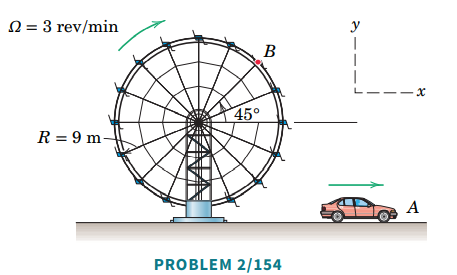

clc, clear all
% We start by listing the knowns:
v_A = 18/3.6; % Speed of the car in m/s.
a_A = 3; % m/s^2

% The Ferris Wheel:
% We start by measur it from rev to rads ->
% 1 rev = 2 * pi.
Omdr_Ferris = 3 * (2*pi)/60; % from 3 rev pr. min to rads pr. sec.
theta = deg2rad(45);

% Now the calculations:
syms i j;
v_BA = vpa(v_A*i - 9 * Omdr_Ferris * (cos(theta)*i - sin(theta)*j),3) 

$$v\_BA = 3.0\,i+2.0\,j$$

# Kapitel 2: Trisser / Constrained Motion of Connected Particles

## *Opgave 2.171*

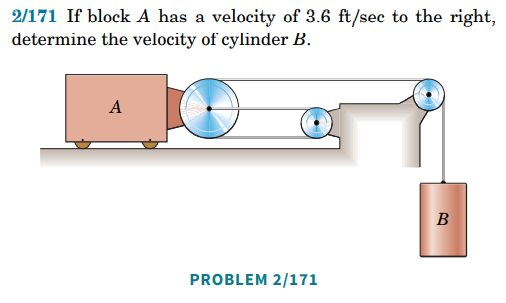

SI versionen af bogen siger, at 3.6 ft = 0.6 meter.

clc, clear all
% We start by listing our knowns.
% At A we have 3 moveable wires. 
% At B we only have 1.
% There is also some constant lengths like the length the the cabel between
% the to smaller rollers.
% This makes the length of the cabel relations:
syms A B t;
c = 1;
L = @(t) 3 * A*t + B*t + c;

% If we differentiate with the respectiv to time we get an expression of
% velocity:
Sym_v = diff(L,t);
v_A = 0.6;
A = v_A;
v_BEqaution = vpa(solve(Sym_v,B),4)

$$v\_BEqaution = -3.0\,A$$

v_B = -3 * A

v_B = -1.8000

## *Opgave 2.172*

# Undervisning D. 21/11 - 22

## Opgave 6/89

syms g m l w

d = l/4;
IG = 1/12 * m * l^2;
I0 = IG + d^2 * m;
U1_2 = m * g * l/4;

eq = U1_2 == 1/2 * I0 * w^2

$$eq = \frac{g\,l\,m}{4}=\frac{7\,l^{2}\,m\,w^{2}}{96}$$

w = vpa(simplify(solve(eq,w)),5)

$$w = \left(\begin{array}{c} -\frac{1.8516\,\sqrt{g}}{\sqrt{l}}\\ \frac{1.8516\,\sqrt{g}}{\sqrt{l}} \end{array}\right)$$

## Opgave 6/91

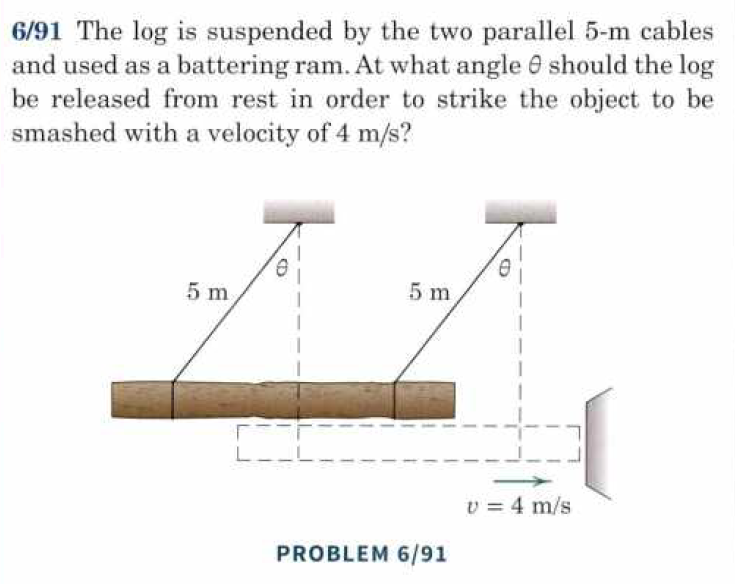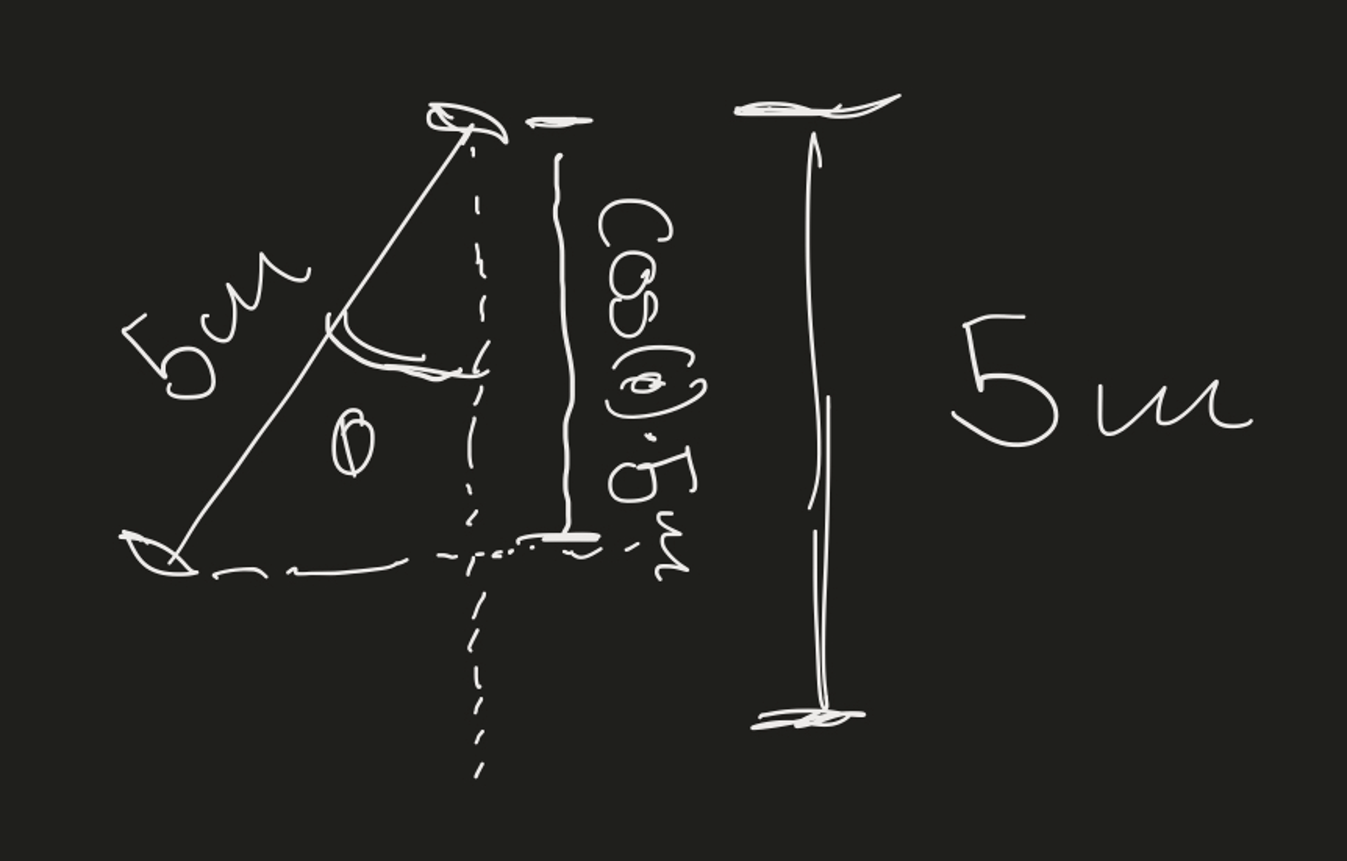

Vi har en bjælke, som har en snor, der er 5 meter lang fra origo. Den er trukket tilbage/hævet x-afstand, hvoraf den også er hævet y-afstand.

Dette definerer vi som første tilfælde.

Næste tilfælde befinder sig x-afstand væk og 5 meter fra origo.

Vi ønsker at kende:

- Vinklen mellem de to tilfælde, som er defineret. 